arr_req = [0,1,2];
K = 16;
C = 16;


[err_train, err_test, Conf] = RC_implementation(K, C, arr_req);

cm = confusionchart(Conf,{'0','1','2','3','4','5','6','7','8','9'})
cm.RowSummary = 'row-normalized';
cm.Title = 'Digit clasification using 8 inputs and 8 layers';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%55

K_vec = 4:4:28;
arr_req = [0, 1, 2];
C_vec = K_vec;

Mn = size(K_vec,2);
err_train_vec = zeros(Mn,1);
err_test_vec = zeros(Mn,1);
%Conf_vec = mlearnlib.graphics.chart.ConfusionMatrixChart.empty(Mn,0);

for i = 1:Mn
    [err_train_vec(i), err_test_vec(i), Conf] = RC_implementation(K_vec(i), C_vec(i), arr_req);
    %cm = confusionchart(Conf,{'0','1','2'})
    %cm.RowSummary = 'row-normalized';
    %cm.Title = 'Digit clasification using 8 inputs and 8 layers';
end

# PC = 126
Elapsed time is 482.073847 seconds.


# PC = 126
Elapsed time is 741.734078 seconds.


# PC = 126
Elapsed time is 995.494877 seconds.


# PC = 126
Elapsed time is 1208.372798 seconds.


# PC = 126
Elapsed time is 1663.861370 seconds.


# PC = 126
Elapsed time is 1663.591694 seconds.


# PC = 126
Elapsed time is 1993.205793 seconds.


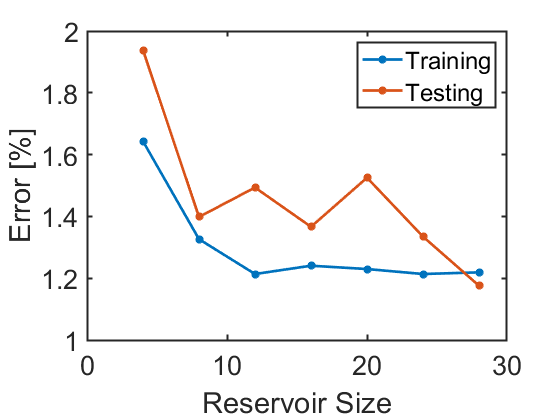

figure; hold on;
plot(K_vec, err_train_vec,'LineWidth',2,'Marker',"*");
plot(K_vec, err_test_vec,'LineWidth',2,'Marker',"*");
legend('Training','Testing')
xlabel('Reservoir Size')
ylabel('Error [%]')
set(gca,'FontSize',20)
set(gca,'linewidth',1.5)
set(gca,'box',1)

figure; hold on;
plot(K_vec, err_train_vec_nor,'LineWidth',2,'Marker',"*","Color",'k');
plot(K_vec, err_test_vec_norm,'LineWidth',2,'Marker',"*","Color",'k',"LineStyle",'--');
plot(K_vec, err_train_vec_alt,'LineWidth',2,'Marker',"*","Color",'b');
plot(K_vec, err_test_vec_alt,'LineWidth',2,'Marker',"*","Color",'b',"LineStyle",'--');
plot(K_vec, err_train_vec_noliq,'LineWidth',2,'Marker',"*","Color",'r');
plot(K_vec, err_test_vec_noliq,'LineWidth',2,'Marker',"*","Color",'r',"LineStyle",'--');
lgd = legend('Training - Series','Testing - Series ','Training - Parallel','Testing - Parallel','Training - Without memory','Testing - Without memory ')

lgd =   Legend (Training - Series, Testing - Series, Training - Parallel, Testing - Parallel, Training - Without memory, Testing - Without memory) with properties:

         String: {'Training - Series'  'Testing - Series'  'Training - Parallel'  'Testing - Parallel'  'Training - Without memory'  'Testing - Without memory'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5417 0.6567 0.3446 0.2440]
          Units: 'normalized'

  Show all properties


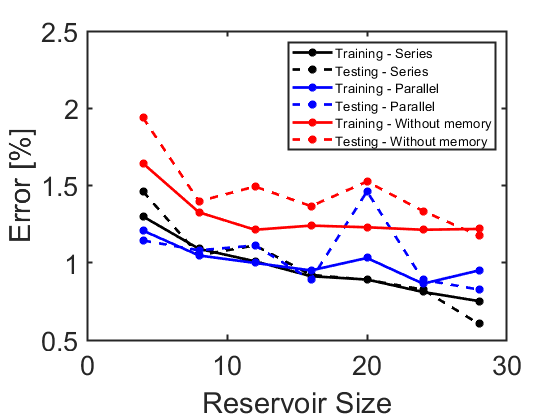

lgd.FontSize = 10;
xlabel('Reservoir Size')
ylim([0.5 2.5])
ylabel('Error [%]')
set(gca,'FontSize',20)
set(gca,'linewidth',1.5)
set(gca,'box',1)